% Step 1: First we must define the step size, (h)*******
h = (1/16);

% Step 2: Next we must define the approximation domain (x)*******
% a = Beginning x domain value
a = 0;
% b = Ending x domain value
b = 20;

% Step 3: Then we must define the number of iterations
n = (b-a)/h;

% Step 4: Then we define the array for the x values for the purpose of the table ouput
% Where n is the number of rows
x = linspace(a,b,n)';

% Step 5a: Now we must define the array for the y values (Array of Zeroes)
% It is defined as a array with n number of rows and 1 column
y = zeros(n,1);

% Step 5b: Now we must define the array for the q values
% The q array represents the approximation values
q = zeros(n,1);

% Step 5c: Now we must define the array for the z values
% The z array represents the error values
z = zeros(n,1);

% Step 6: Next we must set the the initial y value*******
% Because MATLAB cannot start its array indices at zero you must use y(1)
% and correct it in the for-loop
y(1) = (-0.5);

% Step 7:
% Finally we must loop through the construct and set the y' of the ODE, in order to produce approximations

for j = 1:n-1 % This is the correction for line 32 (Adjusting the range so that it handles MATLAB's limitation)
    
    % Next set the analyticalSolution if you want to true values*******
    % Setting this also allows you to find the approximation errors
    global analyticalSolution; analyticalSolution = 1 + (y(1) - 1)* exp(cos(x)-1);
    
    % Now set the y' of the ODE*******
    global y_prime; y_prime = @(x, y)(sin(x)*(1-y));
    
    % Now apply the Euler's Method general formula to your ODE
    y(j+1) = y(j) + (h * y_prime(x(j), y(j)));
    
    % This section is to calculate and display the analytical solution
    % As well as calculate and display the approximation error values
    q(j) = analyticalSolution(j);
    z(j) = abs(analyticalSolution(j) - y(j));
    
    if(j == (n-1))
        q(j+1) = analyticalSolution(j+1);
        z(j+1) = abs(analyticalSolution(j+1) - y(j+1));
    end
end

EndingArray = [x y q z];
T = array2table(EndingArray); % This is the full table
T_tail = tail(T);
T.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
T_tail.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
display(T_tail);

T_tail = 8×4 table
    x-Values    y-Values    Analytical Solutions    Error-Values
    ________    ________    ____________________    ____________

     19.561     0.10687            -0.1768            0.28367   
     19.624     0.14332           -0.12795            0.27127   
     19.687     0.18076          -0.078084            0.25884   
     19.749     0.21878          -0.027718             0.2465   
     19.812     0.25702           0.022685            0.23433   
     19.875     0.29512           0.072702            0.22242   
     19.937     0.33278            0.12195            0.21083   
         20     0.36971             0.1701            0.19961   


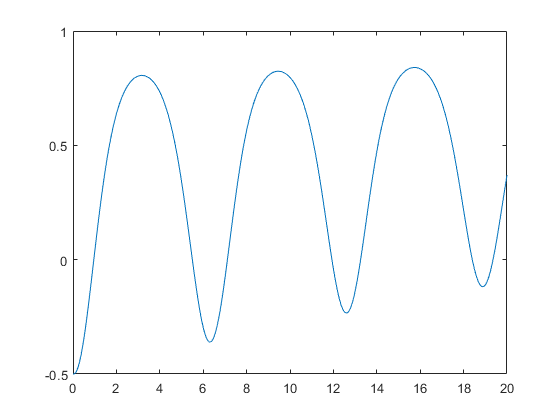

plot(x,y);

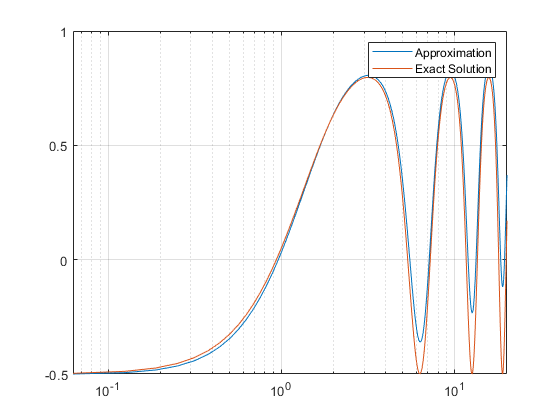

semilogx(x,y,x,q);
legend('Approximation','Exact Solution')
grid on;